## Synchronicity in the network

We need to measure the synchronicity of the network, without worrying about network activity. We'll use the order metric, but use neurons place in time domain, not theta.

Order metric


$$r = \frac{1}{N} \sum_n^N e^{i\theta_n}$$


But instead of theta, we will be using the neurons phase in the TIME domain, call it phi.

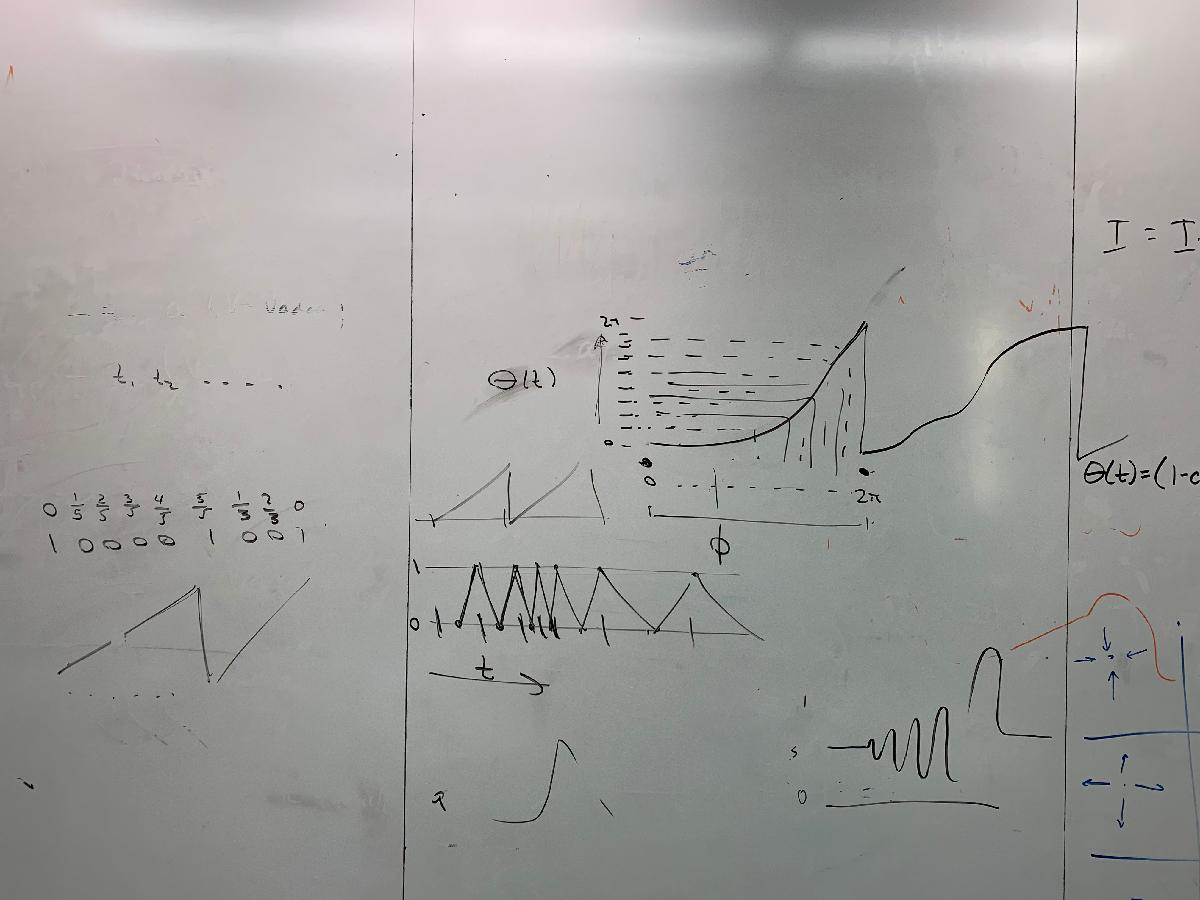

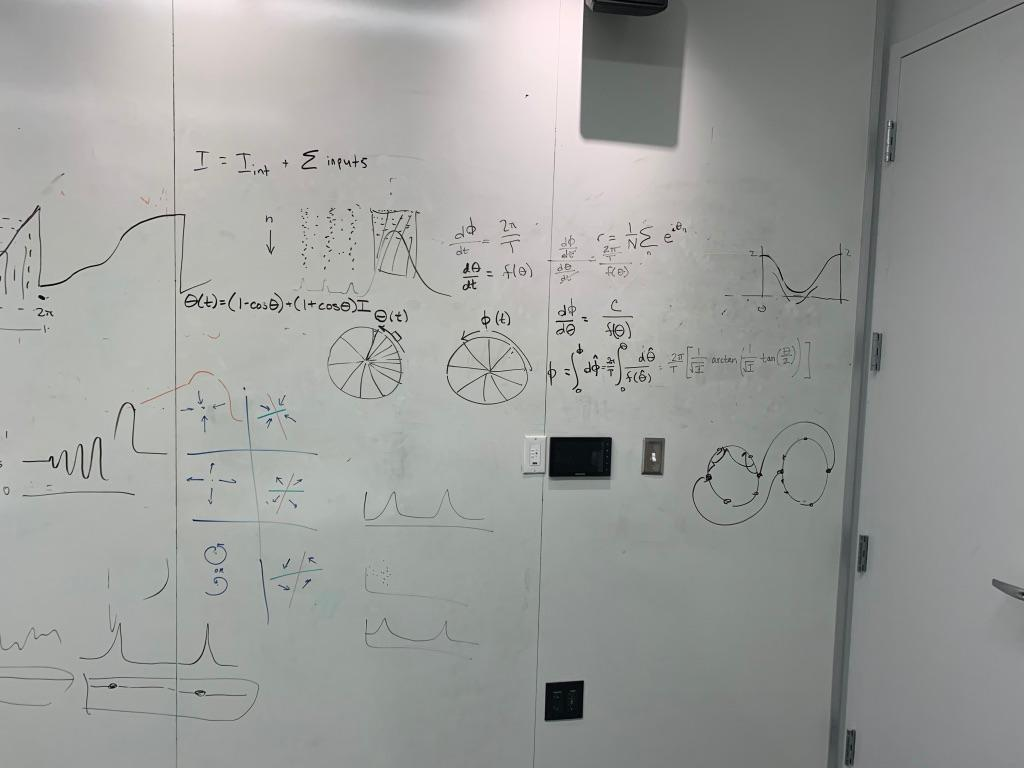

First let's compute a matrix like the raster, but instead of 1s, the value is 2pi. And between the spikes, is a linear growth from 0 to 2pi. This will be our matrix of phis (rows = time, columns = neurons)

r = O.raster;

r(r==1) = 2*pi;

r(isnan(r)) = 0;

% initialize phi
phi = NaN(size(r));

for n = 1:Parameters.n1

   %gaps.(['a' mat2str(i)]) =  find(r(:,i)==2*pi);
   point = find(r(:,n)==2*pi);
   gaps = diff(point);
   
   for k = 1:length(gaps)
       
       fill = linspace(0,2*pi,gaps(k)+1)';
       
       phi(point(k):point(k+1),n) = fill;
       
   end

end

% verify phi works for one neuron

if 0
    plot(O.t, phi(:,randi(Parameters.n1)))
end

Excellent. Now let's compute the order value over time

order = @(N,th) (1/N) * sum( exp( i .* th ) , 2);
% trying omitnan here
order_omitnan = @(N,th) (1/N) * sum( exp( i .* th ) , 2,'omitnan');

% also changed this line
R = order_omitnan(Parameters.n1,phi);

%plot(O.t,abs(R))



Plot it

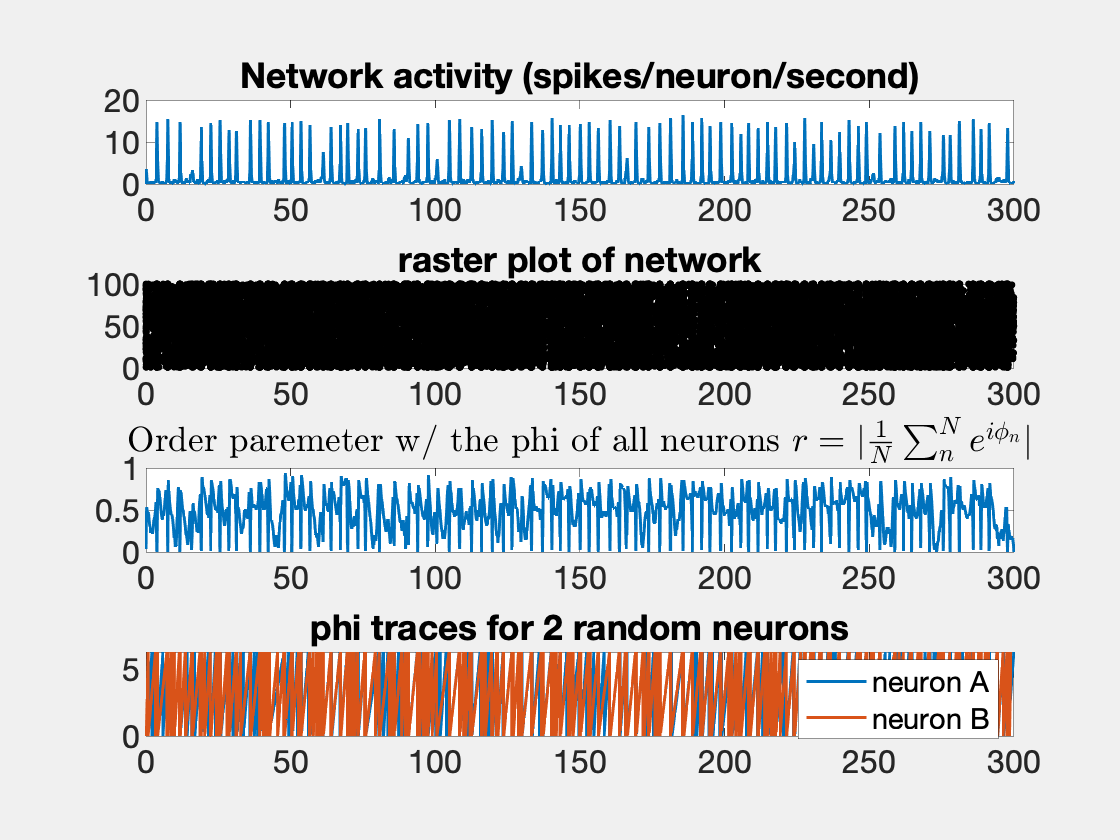

figure; set(gcf,'Visible','on');
ax1=subplot(4,1,1);
plot(O.thappy,O.spikeshappy)
title('Network activity (spikes/neuron/second)')
ax4 = subplot(4,1,2);
for k = 1:Parameters.n1
    plot(O.t/1000,O.raster(:,k)*k,'.k'); hold on;
end
title('raster plot of network')
ax2=subplot(4,1,3); 
plot(O.thappy,abs(R))
title('Order paremeter w/ the phi of all neurons $ r = |\frac{1}{N} \sum_n^N e^{i\phi_n}| $','interpreter','latex')
ax3 = subplot(4,1,4);
n1 = randi(Parameters.n1);
n2 = randi(Parameters.n1);
%plot(O.thappy,phi(:,[n1 n2]))
plot(O.thappy,phi(:,[n1 n2]))
legend('neuron A','neuron B')
title('phi traces for 2 random neurons')

linkaxes([ax1,ax2,ax3],'x');

Wonderful! I notice the synchronicity apears to rise before a spike, then drop quickly, then rise again before falling away. I wonder what a cta looks like.

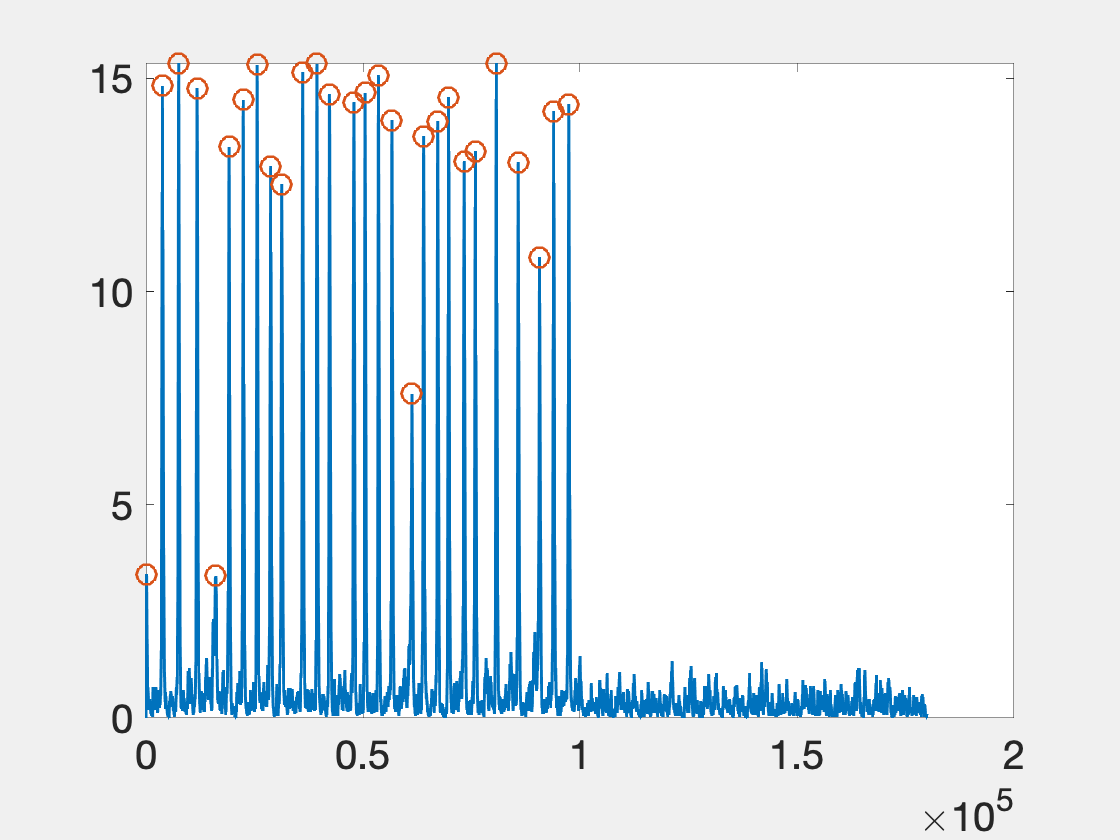

% trying find peaks
figure; set(gcf,'Visible','on');
[pks,locs] = findpeaks(O.spikeshappy,'MinPeakDistance',1000/Parameters.dt, ...
                       'MinPeakHeight', mean(O.spikeshappy)+std(O.spikeshappy));
plot(O.t,O.spikeshappy); hold on;
plot(O.t(locs),pks,'o')

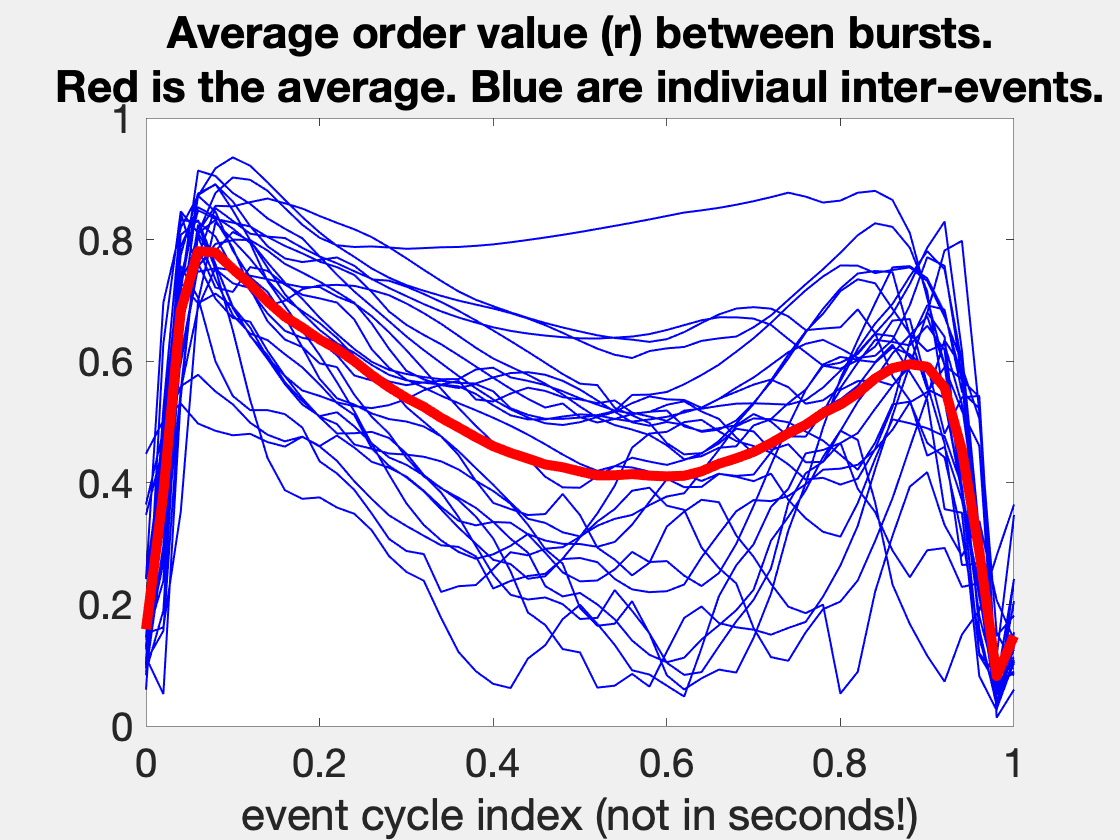


% make up queiry points
sampnts = 0:1/50:1;
% initialize output
vq = zeros(length(sampnts),length(pks)-1);

for k = 1:length(pks)-1
    
    % generate the signal between events
    v = abs(R(locs(k):locs(k+1)));
    % generate dummy 0 to 1 time scaling
    x = linspace(0,1,length(v));
    
    
    vq(:,k) = interp1(x,v,sampnts);
    
end

figure;  set(gcf,'Visible','on');
plot(sampnts,vq,'b','linewidth',1); hold on
plot(sampnts,mean(vq,2),'r','linewidth',5)
title({'Average order value (r) between bursts.','Red is the average. Blue are indiviaul inter-events.'})
xlabel('event cycle index (not in seconds!)');